## Least Squares Regression

In this livescript, you will learn how

- To apply least squares regression

Given a set of data points, we may approximate the relationship by assuming a functional relationship $y_{i}=f(x_{i};\textbf{a})$, where $\textbf{a}$ the parameters defining the problem.

For a linear relationship


$$y=a_{0}+a_{1}x$$


$a_{0}$ and $a_{1}$ are the parameters.

Define the error as


$$e_{i}=|y_{i}-f(x_{i})|$$


Then to determine $f$, we want to choose out $a_{i}$'s such that it minimises the total error.

The total square error is therefore 


$$S=\sum^{N}_{i=1}{e_{i}^{2}$$


*Equation 1.*

Our goal is to find the $a_{i}$'s that minimise $S$. Thus, we compute the derivatives with respect to $a_{i}$ and set it to zero.

Thus, we obtain the set of equations 


$$\pmatrix{\frac{\partial S}{\partial a_{1}}\cr\frac{\partial S}{\partial a_{2}}\cr\vdots}
=
\pmatrix{\sum^{N}_{i=1}{2e_{i}\frac{\partial e_{i}}{\partial a_{1}}} \cr \sum^{N}_{i=1}{2e_{i}\frac{\partial e_{i}}{\partial a_{2}}} \cr \vdots}
=
\pmatrix{0 \cr 0 \cr \vdots}$$


*Equation 2.*

Eq. (2) defines the least squares problem.

As an example, we consider the set of data

x = [1.2712    1.6767    3.0656    3.7720    4.9970    6.0655    6.7446    7.7158    9.1419    9.8807];
y = [0.9835    1.5948    3.0609    4.0504    5.3752    5.7974    7.1778    7.8748    8.6854    9.7225];

A good idea before we conduct a regression analysis is to plot a scatter plot, so that we get an idea of what the functional relationship is

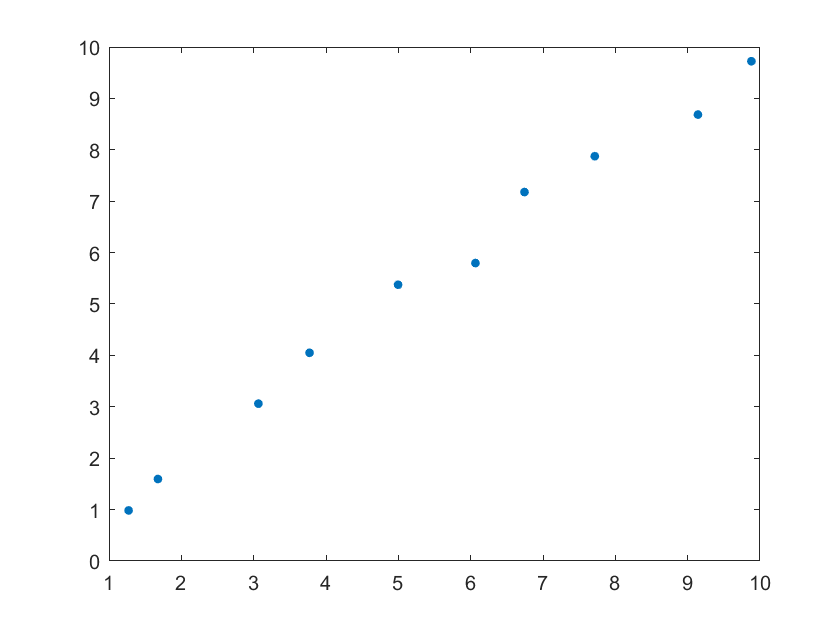

figure(1)
plot(x,y,'.','MarkerSize',15)

The data is quite linear, so let's assume a model of the form


$$y=a_{0}+a_{1}x$$


**Part 1:**

(a)        Show that the leasts squares problem is given by


$$\pmatrix{\sum^{10}_{i=1}{x_{i}^{2}} & \sum^{10}_{i=1}{x_{i}} \cr \sum^{10}_{i=1}{x_{i}^{2}} & 10}
\pmatrix{a_{1} \cr a_{0}}
=
\pmatrix{\sum^{10}_{i=1}{x_{i}y_{i}} \cr \sum^{10}_{i=1}{y_{i}}}$$


*Equation 3.*

If we have a vector $\texttt{x}$, that contains all the $x_{i}$s, MATLAB has this great function $\texttt{sum}$, which as you may have guessed, determines the sum of all the elements of $\texttt{x}$.

The following code uses $\texttt{sum}$ to assemble the right and left-hand-side of Eq. (3).

A = [sum(x.^2) sum(x);
     sum(x)    10];
c = [sum(x.*y);
     sum(y)];

Solving for the coefficients $\{a\}$ and plotting

a = A\c

a =     0.9908
    0.0493


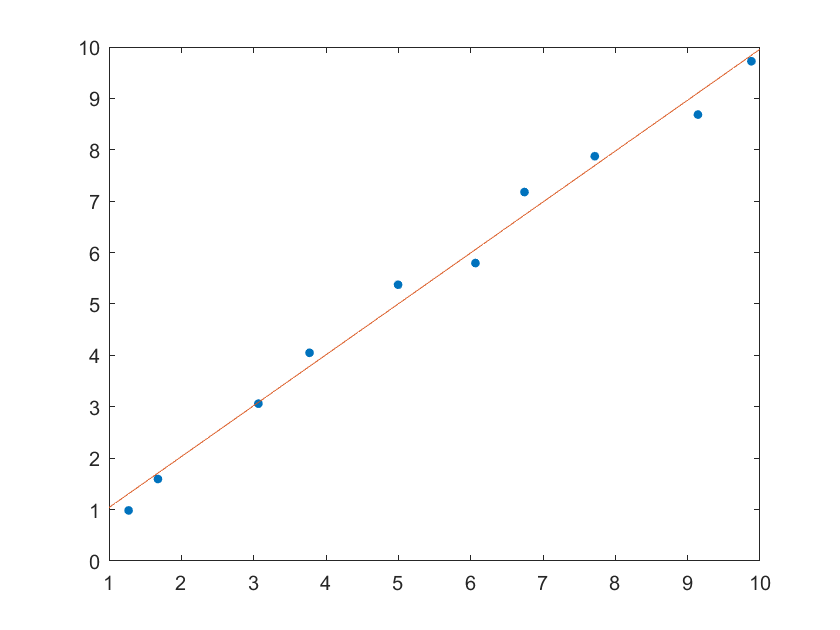


xplot = linspace(1,10,100);
f = a(2) + a(1)*xplot;

figure(2)
plot(x,y,'.','MarkerSize',15)
hold on
plot(xplot,f)
hold off

(b)        Run this code and see if it provides a good fit.

(c)        Use $\texttt{fitlm}$ or the 'Basic Fitting' toolbox to check the answer.

fitlm(x,y)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    0.049323     0.21852    0.22571       0.82708
    x1              0.99077    0.035635     27.803    3.0226e-09


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 0.32
R-squared: 0.99,  Adjusted R-Squared: 0.988
F-statistic vs. constant model: 773, p-value = 3.02e-09

You may have noticed that $\texttt{fitlm}$ gives you quite a few outputs, including $R^{2}$, rms error, etc.

To obtain a estimate of how good the regression is, a common measure is the $R^{2}$ value. Define 


$$\bar{y}=\frac{1}{N}\sum^{N}_{i=1}{y_{i}}$$


as the mean value of the measurements, which can be used as a crude estimate of the model.

In MATLAB, we can find this using the $\texttt{mean}$ command, whose input is a vector of the values.

ybar = mean(y)

Then the $R^{2}$ value is defined as


$$R^{2}=1-\frac{\sum^{N}_{i=1}{(y_{i}-f_{i}})^{2}}{\sum^{N}_{i=1}{(y_{i}-\bar{y}})^{2}}$$


*Equation 4.*

NOTES:

- The numerator may be interpreted as the residual sum of squares (i.e. how well $f$ models the data)

- The denominator on the other hand is the total sum of squares (i.e. how well the mean models the data)

- $R^{2}$ varies between $-1\leq R^{2} \leq 1$.

Applying this in MATLAB

yi = y;
fi = a(2) + a(1)*x;


R2 = 0.9898

R2 = 1-(sum((yi-fi).^2))/(sum((yi-ybar).^2))

which does match the results we got from $\texttt{fitlm}$.

There is a direct way of finding the $R^{2}$ value in MATLAB. And it is based on the relation between $R^{2}$ and a statistical measure called the Pearson correlation coefficient defined as


$$r^{2}_{y,f}=\frac{(\text{Cov}(y,f))^{2}}{\text{Var}(y)\text{Var}(f)}$$


Under some general assumptions, the $R^{2}$-value will be given by


$$R^{2}=r^{2}_{y,f}$$


Thus, we have

cov(yi,fi).^2/(var(yi)*var(fi))

ans =     1.0103    0.9898
    0.9898    0.9898


Alternatively, this can be determined using the function $\texttt{corrcoef}$, which takes the data $\texttt{y}$ and $\texttt{f}$ as inputs, and outputs a matrix of the cross correlations between  $\texttt{y}$ and $\texttt{f}$.

corrcoef(yi,fi).^2

ans =     1.0000    0.9898
    0.9898    1.0000
